# Práctica 2 - Cortocircuitos II - Apartado B

Cortocircuito simétrico (F30) en el punto F1 en función de x, usando la matriz de barras

## Sistemas Eléctricos y de Potencia

Subgrupo 10

format shortG
sympref('FloatingPointOutput', true);
if ~exist('Sbase', 'var')
    evalc('Practica1A');
end

## Circuito equivalente (en secuencia directa)

% Datos
Ubase_F1 = Ubase1;
Ibase_F1 = Sbase/(sqrt(3)*Ubase_F1);
Upf_F1 = 1.05;

% Valor de x (10% - 90%)
x_val =70;

% Valores de todas las admitancias iniciales
Y1N = 1/(ZT1pu(1) + ZM1pu(1));
Y12 = 1/ZL12pu(1);
Y14 = 1/ZL14pu(1);
Y2N = 1/(ZT2pu(1) + ZG2pu(1));
Y23 = 1/ZL23pu(1);
Y24 = 1/ZL24pu(1);
Y3N = 1/(ZT3pu(1) + ZG3pu(1));
Y35 = 1/ZL35pu(1);
Y4F1 = 1/ZL4Xpu(1);
Y5N = 1/(ZT5pu(1) + ZM2pu(1));
Y5F1 = 1/ZL5Xpu(1);

## Matriz de admitancias (de barras)

El índice 6 corresponde al punto de falta F1 

Ybarras = [Y1N+Y12+Y14, -Y12           , 0           , -Y14        , 0           , 0        ;
           -Y12       , Y2N+Y12+Y23+Y24, -Y23        , -Y24        , 0           , 0        ;
           0          , -Y23           , Y3N+Y23+Y35 , 0           , -Y35        , 0        ;
           -Y14       , -Y24           , 0           , Y14+Y24+Y4F1, 0           , -Y4F1    ;
           0          , 0              , -Y35        , 0           , Y5N+Y35+Y5F1, -Y5F1    ;
           0          , 0              , 0           , -Y4F1       , -Y5F1       , Y4F1+Y5F1 ];
Ybarras = simplify(Ybarras) % se simplifica para que se vea mejor

$$Ybarras = \begin{array}{l} \left(\begin{array}{cccccc} -31.7847\,\mathrm{i} & 24.8914\,\mathrm{i} & 0 & 6.2229\,\mathrm{i} & 0 & 0\\ 24.8914\,\mathrm{i} & -45.9485\,\mathrm{i} & 12.4457\,\mathrm{i} & 4.3560\,\mathrm{i} & 0 & 0\\ 0 & 12.4457\,\mathrm{i} & -21.6415\,\mathrm{i} & 0 & 4.3560\,\mathrm{i} & 0\\ 6.2229\,\mathrm{i} & 4.3560\,\mathrm{i} & 0 & -\frac{4.3560\,\mathrm{i}}{x}-10.5789\,\mathrm{i} & 0 & \frac{4.3560\,\mathrm{i}}{x}\\ 0 & 0 & 4.3560\,\mathrm{i} & 0 & -\frac{7.1054e-18\,\left(6.7536e+17\,x\,\mathrm{i}-1.2884e+18\,\mathrm{i}\right)}{x-1} & \sigma_{1}\\ 0 & 0 & 0 & \frac{4.3560\,\mathrm{i}}{x} & \sigma_{1} & \frac{4.3560\,\mathrm{i}}{x\,\left(x-1\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{4.3560\,\mathrm{i}}{x-1} \end{array}$$

## Matriz de impedancias

Zbarras = inv(Ybarras);
Zbarras = simplify(Zbarras) % se simplifica para que se vea mejor

$$Zbarras = \begin{array}{l} \left(\begin{array}{cccccc} 0.1404\,\mathrm{i} & 0.1095\,\mathrm{i} & 0.0822\,\mathrm{i} & 0.1182\,\mathrm{i} & 0.0954\,\mathrm{i} & \sigma_{4}\\ 0.1095\,\mathrm{i} & 0.1136\,\mathrm{i} & 0.0834\,\mathrm{i} & 0.1049\,\mathrm{i} & 0.0896\,\mathrm{i} & \sigma_{3}\\ 0.0822\,\mathrm{i} & 0.0834\,\mathrm{i} & 0.1133\,\mathrm{i} & 0.0862\,\mathrm{i} & 0.0949\,\mathrm{i} & \sigma_{1}\\ 0.1182\,\mathrm{i} & 0.1049\,\mathrm{i} & 0.0862\,\mathrm{i} & 0.1844\,\mathrm{i} & 0.1288\,\mathrm{i} & \sigma_{5}\\ 0.0954\,\mathrm{i} & 0.0896\,\mathrm{i} & 0.0949\,\mathrm{i} & 0.1288\,\mathrm{i} & 0.2157\,\mathrm{i} & \sigma_{2}\\ \sigma_{4} & \sigma_{3} & \sigma_{1} & \sigma_{5} & \sigma_{2} & -0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=0.0087\,x\,\mathrm{i}+0.0862\,\mathrm{i}\\ \sigma_{2}=0.0869\,x\,\mathrm{i}+0.1288\,\mathrm{i}\\ \sigma_{3}=-0.0153\,x\,\mathrm{i}+0.1049\,\mathrm{i}\\ \sigma_{4}=-0.0229\,x\,\mathrm{i}+0.1182\,\mathrm{i}\\ \sigma_{5}=-0.0556\,x\,\mathrm{i}+0.1844\,\mathrm{i} \end{array}$$

## Impedancia total equivalente entre F1 y N

Correspondiente con el valor (6,6) de la matriz de impedancias

% Valor por unidad en función de x
ZF1N(x) = Zbarras(6,6)

$$ZF1N(x) = -0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}$$


% Valor por unidad sustituyendo x
ZF1N(x_val/100)

$$ans = 0.1953\,\mathrm{i}$$

## Valor de la corriente trifásica de cortocircuito simétrico (F30) en el punto F1

Solo existe corriente en la secuencia directa, siendo esta igual a la corriente de la fase A, e igual en módulo pero desfase de -120º y 120º en las fases B y C, respectivamente

% Valor por unidad en función de x
J1F1pu(x) = Upf_F1/ZF1N

$$J1F1pu(x) = \frac{1.0500}{-0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}}$$


% Valor por unidad sustituyendo x
J1F1pu(x_val/100)

$$ans = -5.3753\,\mathrm{i}$$


% Valor real en función de x
J1F1(x) = J1F1pu*Ibase_F1

$$J1F1(x) = \frac{459.2559}{-0.0871\,x^{2}\,\mathrm{i}+0.1183\,x\,\mathrm{i}+0.1844\,\mathrm{i}}$$


% Valor real sustituyendo x
J1F1(x_val/100)

$$ans = -2.3511e+03\,\mathrm{i}$$

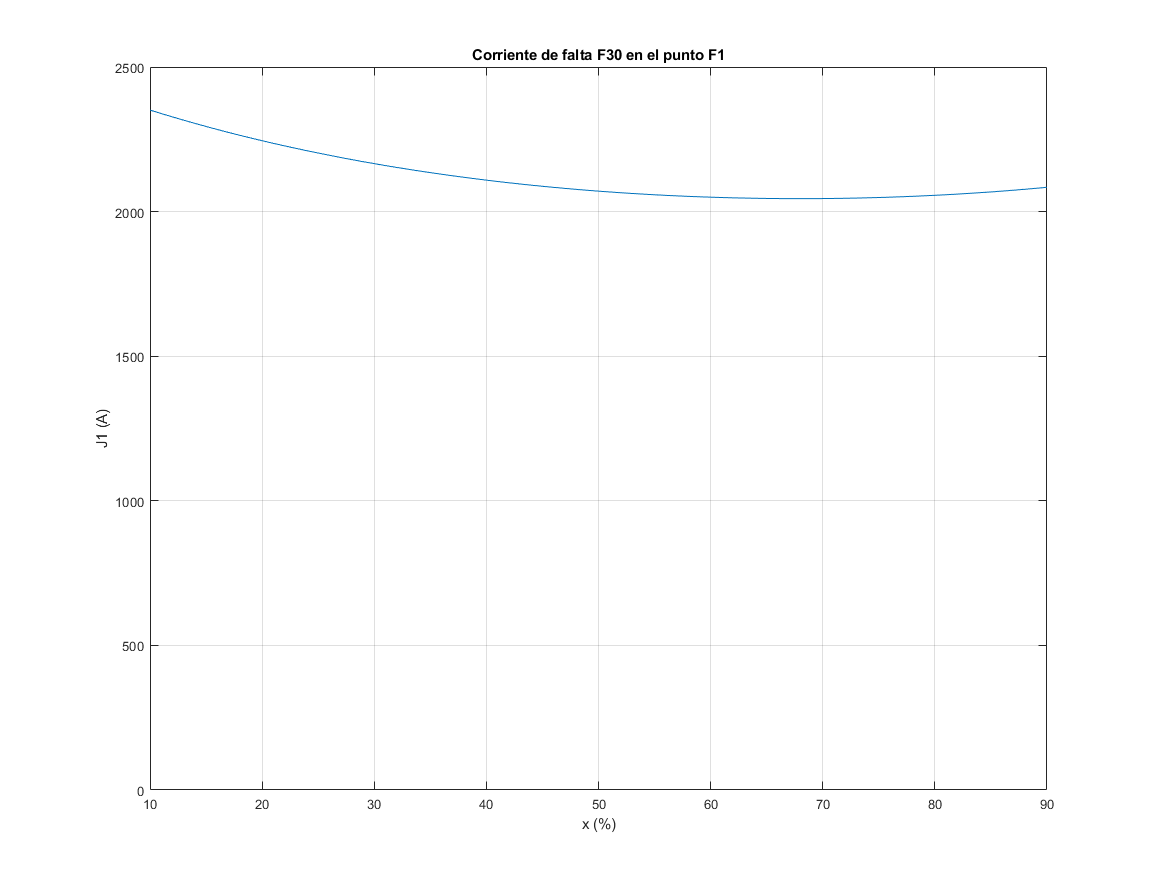


% Representación gráfica de la corriente de falta en función de x (en
% módulo)
xF1 = 10:90;
plot(xF1, abs(J1F1(xF1/100)));
title('Corriente de falta F30 en el punto F1');
xlabel('x (%)');
ylabel('J1 (A)');
grid on;
ylim([0, 2500]);